## This exercise explores periodic signals and their representation in the spectral domain

`Copyright © 2019 Danica Roth <droth@mines.edu>`

`GNU General Public License`

First, clear working memory and figures (good practice for any Matlab script):

clear
close all

## Sinusoidal Signals

### Sinusoids in the spatial domain

A **sine wave** or **sinusoid** is a continuous mathematical function describing a periodic oscillation:

             $y\left(x\right)=A\;\sin \left(2\pi \;f\;x\;+\;\phi \right)+D=A\;\sin \left(\omega \;x\;+\;\phi \right)+D$,

where   $A=\textrm{amplitude}$

            
$$f=\textrm{frequency}\;\left(\textrm{cycles}\;\textrm{per}\;\textrm{unit}\;x\right)$$


            
$$\omega =2\pi f=\textrm{angular}\;\textrm{frequency}\;\left(\textrm{radians}\;\textrm{per}\;\textrm{unit}\;x\right)$$


            
$$\phi =\textrm{phase}\;\textrm{offset}\;\left(\textrm{in}\;\textrm{radians}\right)$$


            
$$D=\textrm{mean}\;\textrm{offset},\;\textrm{in}\;\textrm{signal}\;\textrm{processing}\;\textrm{also}\;\textrm{called}\;\textrm{the}\;\textrm{DC}\;\textrm{component}$$


In this example, we will assume $D=0$ for simplicity.

Here, we are writing our sine wave as a function of $x$--which could be any variable, really. If we assume $x$ represents space, then this function lives in the **spatial domain**, i.e., it varies periodically in space. If we substitute $t$ or time for $x$, we would then have a function that is periodic in the **time domain**.

Next, we'll define an [anonymous function](https://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html) (syntactically denoted by the @ symbol) to easily create a sine wave $y\left(x\right)$ for any given $x$ array (which we will also define at this point) and set of input parameters $A$, $f$ and $\phi$ (which you will set below).

sine = @(x,A,f,phi,D) A.*sin(2.*pi.*f.*x + phi) + D; %anonymous function

We can plot this function as a symbolic expression using MATLAB's [Symbolic Math Toolbox](https://www.mathworks.com/products/symbolic.html) (which you must have enabled to run this section of the exercise--if you do not have it, the code below will just skip this section).

#### Play with the sliders below until you're sure you understand how each parameter controls the sinusoid.

$$y = \text{D}+A\,\sin\left(\varphi +2\,\pi \,f_{0}\,x\right)$$

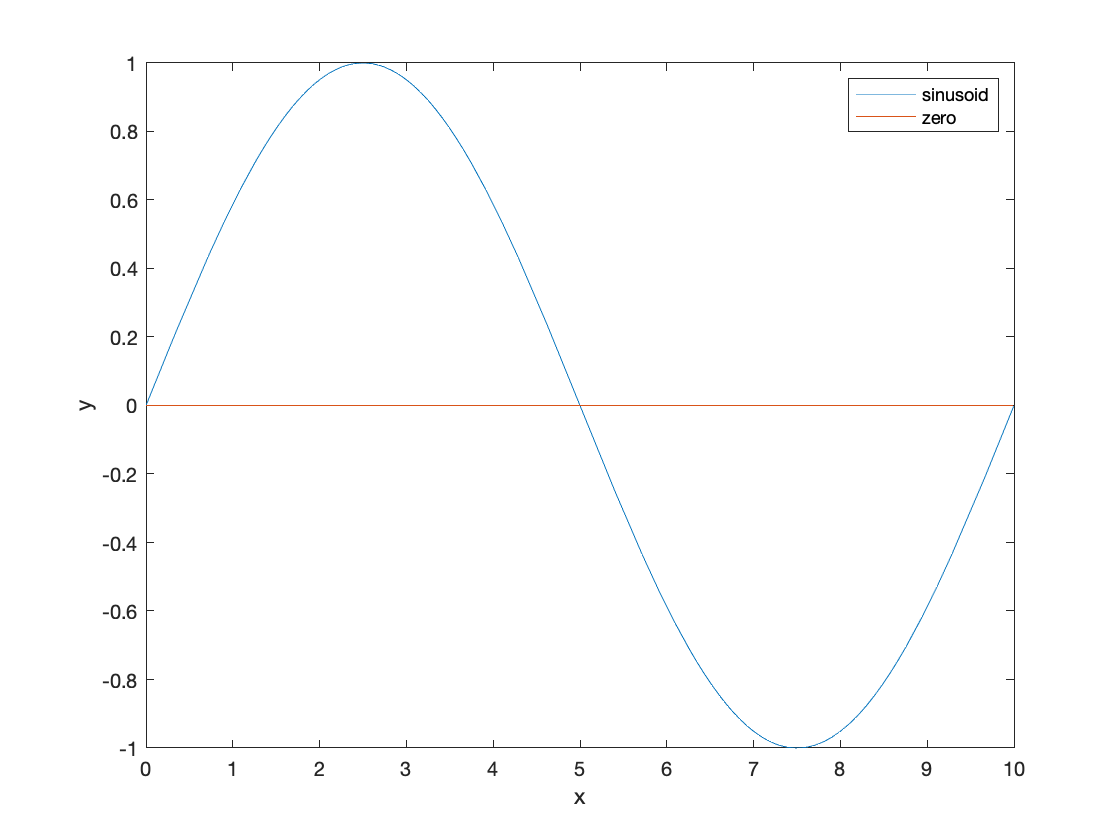

if contains(struct2array(ver), 'Symbolic Math Toolbox')
    syms x A f_0 phi D %create symbolic variables x, A, f, phi and D
    y = sine(x,A,f_0,phi,D) %call the anonymous function above to create a symbolic dependent variable y
    
    %Set parameters for the sine wave
    Aset = 1; %amplitude
    f_0set = 0.1; %frequency
    phiset = 0; %phase
    Dset = 0; %phase
    
    %Plot the sine wave
    figure(1);clf
    fplot(x,subs(y,[A f_0 phi D],[Aset f_0set phiset Dset]),[0 10])
    hold on
    plot([0 10],[0 0])
    xlabel('x')
    ylabel('y')
    legend('sinusoid','zero')
end

#### Now we'll generate a discretized sine wave composed of 3 different components, or 3 different sine waves either added together or appended end-to-end. 

Play with the parameters below until you are clear on how they affect the shape of the sine wave function, which is plotted below.

approach = 'sumwaves'; %we can either append or sum the 3 waveforms below. Experiment to see each option.

%Set underlying parameters for component sine waves
%Component 1
A1 = 5; %amplitude
f1 = 0.4; %frequency
phi1 = 2.5; %phase
prc1 = 1; %100%

%Component 2
A2 = 1; %amplitude
f2 = 20; %frequency
phi2 = 0; %phase
prc2 = 1; %fractional signal length relative to component 1

%Component 3
A3 = 2; %amplitude
f3 = 93.4; %frequency
phi3 = 0.4; %phase
prc3 = 1; %fractional signal length relative to component 1

%Create a table listing relative values of each component for quick
%reference later
Amplitude = [A1 A2 A3]';
Frequency = [f1 f2 f3]';
Phase = [phi1 phi2 phi3]';
RelativeFraction = [prc1 prc2 prc3]'; %fractional signal length relative to component 1
TotalFraction = [prc1 prc2 prc3]'./sum([prc1 prc2 prc3]); %fraction of total signal length

T = table(Amplitude,Frequency,Phase,RelativeFraction,TotalFraction);

%Generate dataset
lengthx = 5; %length of the discrete x-array
dx = 0.0001; %sample interval
x = 0:dx:lengthx; %discrete x-array
N = numel(x); %number of samples in x
if strcmp(approach,'sumwaves')
    y1 = sine(x,A1,f1,phi1,0);
    y2 = sine(x(1:ceil(prc2*N)),A2,f2,phi2,0);
    y3 = sine(x(1:ceil(prc3*N)),A3,f3,phi3,0);
    y = y1 + [y2 zeros(1,floor((1-prc2)*N))] + [y3 zeros(1,floor((1-prc3)*N))];
elseif strcmp(approach,'appendwaves') % length is percent of
    N1 = round(N/(1+prc2+prc3));
    N2 = round(prc2*N1);
    N3 = N-N1-N2;
    y1 = sine(x(1:N1),A1,f1,phi1,0);
    y2 = sine(x(N1+1:N1+N2),A2,f2,phi2,0);
    y3 = sine(x(N1+N2+1:N),A3,f3,phi3,0);
    y = [y1 y2 y3];
end

disp(T); %display the table of parameter values for reference

    Amplitude    Frequency    Phase    RelativeFraction    TotalFraction
    _________    _________    _____    ________________    _____________

        5           0.4        2.5            1               0.33333   
        1            20          0            1               0.33333   
        2          93.4        0.4            1               0.33333   



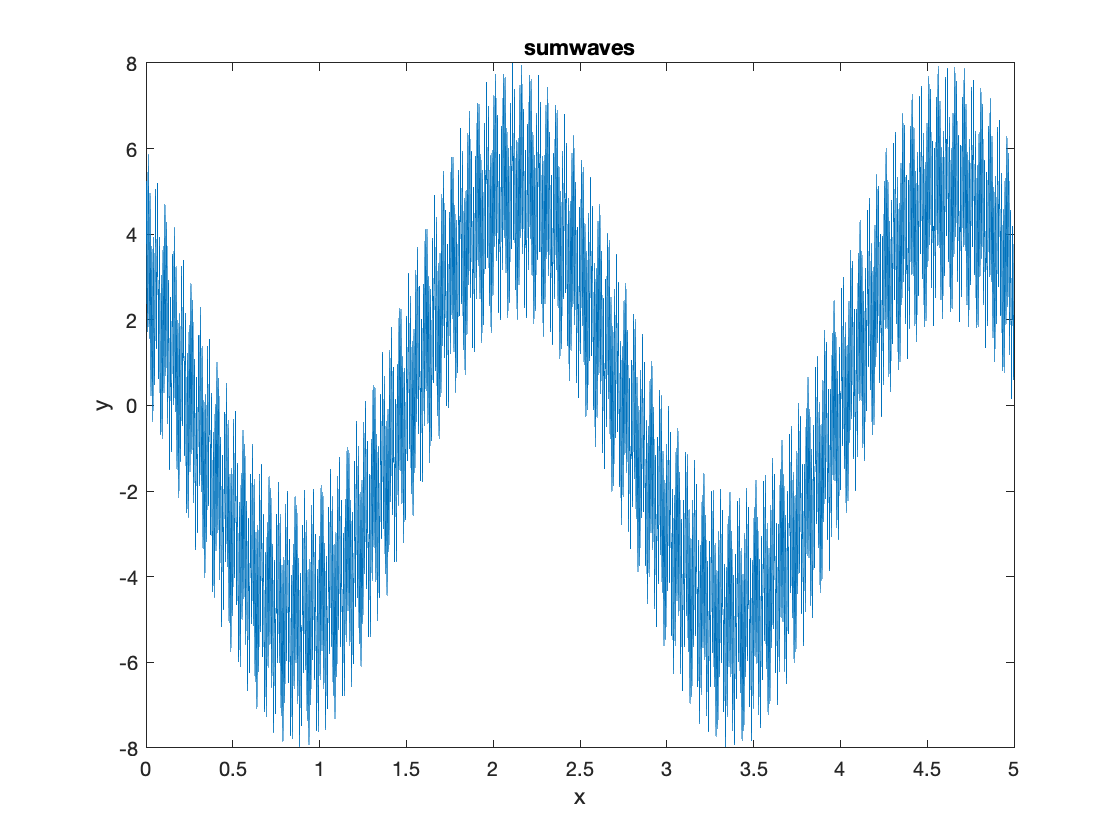


%Plot the "continuous" data
figure(1);clf
plot(x,y)
xlabel('x')
ylabel('y')
title(approach)

## Fourier transforms, spectral power and the frequency domain

The fourier transform (${\displaystyle {\mathcal {F}}$) is a mathematical transform that maps a function to the frequency domain--i.e., decomposes it from the {spatial, temporal, etc.} domain into its {spatial, temporal, etc.} frequencies. The fourier transform of signal $y\left(x\right)$ is denoted here as $\hat{Y} \left(f\right)=$${\displaystyle {\mathcal {F}}\{y(x)\}}$. $\hat{Y}$ is a function of frequency $f$, and can be defined as:

            
$$\hat{Y} \left(f\right)=$$

$${\displaystyle {\mathcal {F}}\{y(x)\}}$$

$$=\int_{-\infty }^{\infty } y\left(x\right)e^{-2\pi ifx} \;dx$$


*(Also note that there are multiple valid conventions around the definition of a fourier transform, so you may see a range of similar but slightly different definitions elsewhere.)*

The fourier transform of our sinusoid is a delta function, which is non-zero only at the sine wave's frequency. We can take the inverse fourier transform of $\hat{Y} \left(f\right)$ to recover $y\left(x\right)$. We won't really be focusing on fourier transforms or their inverses, however, because they are only relevant for continuous functions. When working with real data, which is discrete, we generally use a range of discretized methods based on the discrete fourier transform (DFT) or fast fourier transform (FFT) algorithms--if you decide to pursue the use of spectral analysis in your work, it's worth reading up on these and other spectral methods, but we won't be diving into them for this exercise. Instead we'll be working with some of their most common derivative products, the **power spectrum** and **power spectral density**.

### The power spectrum of a periodic function

The power spectrum of a periodic function is 

Next, we'll use the periodogram function to calculate the *power spectrum* $\hat{P}$ of the sinusoid you constructed above.

The periodogram function calculates a power spectrum: 

            
$$\hat{P_y } \left(f\right)={\left|\sum_{n=0}^{N-1} y_n e^{-2\pi \textrm{ifn}/f_s } \right|}^2 \;\;,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;-\frac{f_s }{2}<f<\frac{f_s }{2}$$


where  $f=\textrm{frequency}\;\left(\textrm{cycles}\;\textrm{per}\;\textrm{unit}\;x\right)$  

           
$$x_n =\textrm{the}\;n^{\textrm{th}} \;\textrm{element}\;\textrm{of}\;\textrm{independent}\;\textrm{variable}\;\textrm{array}\;x$$


           
$$N=\textrm{the}\;\textrm{length}\;\textrm{of}\;x$$


           
$$i=\textrm{the}\;\textrm{imaginary}\;\textrm{number}$$


           
$$f_s =\frac{1}{\triangle x\;}=\textrm{the}\;\textrm{sampling}\;\textrm{frequency}$$
 

           (where $\triangle x\;$is the sample interval, i.e., `dx`)

From the power, we 

fs = 1/dx; %sampling rate (has units of samples/x_units)
nfft = length(y); %number of samples to use for calculating spectrum

%Calculate power spectrum using periodogram function
[Pp,fp] = periodogram(y,[],nfft,fs,'power','onesided');

%Calculate power spectral density using periodogram function
[PSD,fPSD] = periodogram(y,[],nfft,fs,'psd','onesided');

For reasons more complicated than we will go into here, when using the above syntax, the output of the periodogram function represents only the positive frequency content (one side) of what is known as a *2-sided spectrum*. In a two-sided spectrum, the spectrum is symmetric around 0--half the power is contained in positive frequencies, and half is contained in negative frequencies. Because positive and negative frequencies are indistinguishable in most real-world signals, the negative frequency information is redundant and can simply be discarded to produce a *1-sided spectrum* (this has already been done in the output of the `periodogram` function--notice the output frequency array `fp` starts at 0). 

However, because spectral power is a conserved quantity, we must **recover the power from those duplicate negative frequencies by multiplying the positive frequency spectrum by 2** (be careful however, as this can vary depending on the syntax you use... it's always wise to run spectral analysis on synthetic data to make sure it's doing what you think it is before applying it to real data and potentially misinterpreting your results--errors around unit conversion, mistaking frequency for radial frequency, etc. are very common!)

PSD = 2.*PSD; %recover power from negative frequencies
Pp = 2.*Pp; %recover power from negative frequencies
Ap = ((Pp).^(1/2)).'; %amplitude spectrum

Finally, let's plot the power and amplitude spectra, and compare the plots to the parameters you originally set for the sinusoid.

disp(T); %display the table of parameter values for reference

    Amplitude    Frequency    Phase    RelativeFraction    TotalFraction
    _________    _________    _____    ________________    _____________

        5           0.4        2.5            1               0.33333   
        1            20          0            1               0.33333   
        2          93.4        0.4            1               0.33333   



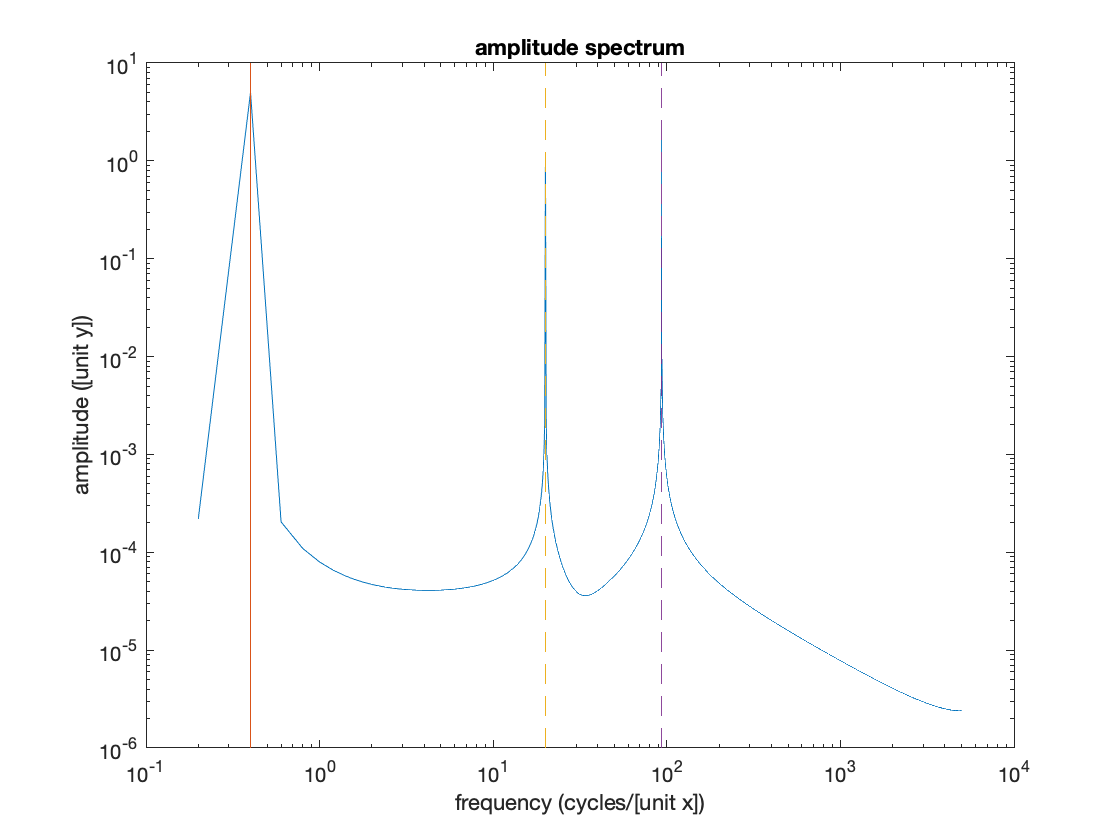


%Plot amplitude spectrum
figure(2);clf
loglog(fp,Ap);
yr = get(gca,'YLim');%get y-limit for current axes 
hold on
loglog([f1 f1],yr,'--',[f2 f2],yr,'--',[f3 f3],yr,'--')
ylabel('amplitude ([unit y])')
xlabel('frequency (cycles/[unit x])')
title('amplitude spectrum')

[A_peaks A_peaksloc] = findpeaks(Ap,'SortStr','descend','NPeaks',3);
disp(['Peak frequencies: ',num2str(fp(A_peaksloc)')])

Peak frequencies: 0.399992      93.3981      19.9996


disp(['Peak amplitudes:  ',num2str(A_peaks)])

Peak amplitudes:  5      1.9997           1


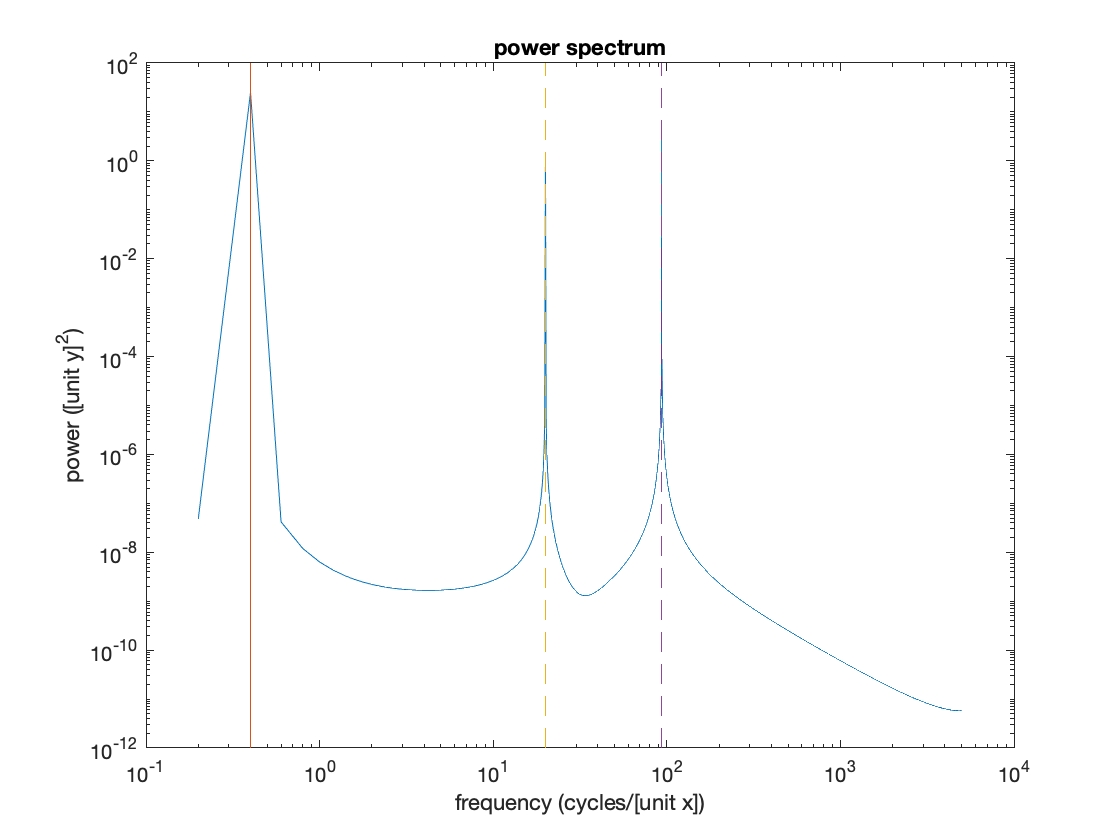


%Plot power spectrum
figure(3);clf
loglog(fp,Pp);
yr = get(gca,'YLim');%get y-limit for current axes 
hold on
loglog([f1 f1],yr,'--',[f2 f2],yr,'--',[f3 f3],yr,'--')
ylabel('power ([unit y]^2)')
xlabel('frequency (cycles/[unit x])')
title('power spectrum')

[P_peaks P_peaksloc] = findpeaks(Pp,'SortStr','descend','NPeaks',3);
disp(['Peak frequencies: ',num2str(fp(P_peaksloc)')])

Peak frequencies: 0.399992      93.3981      19.9996


disp(['Peak power:  ',num2str(P_peaks')])

Peak power:  25      3.99877      1.00001


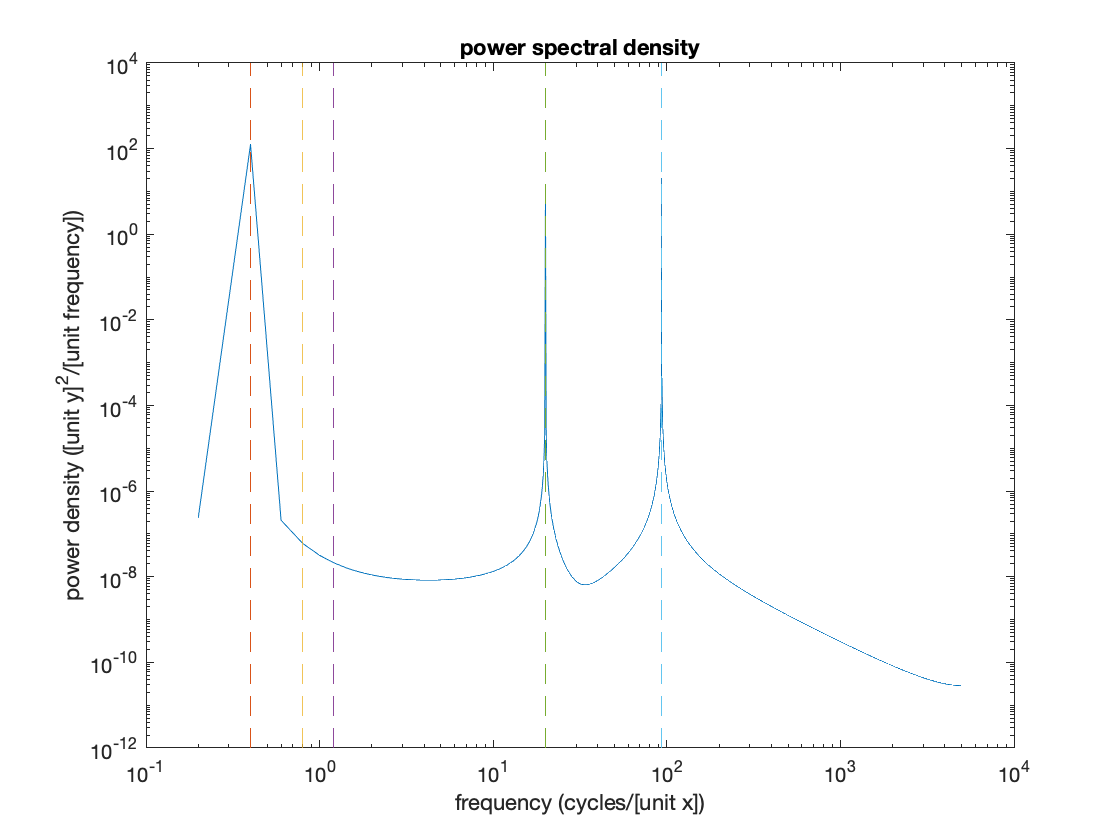


%Plot power spectral density (PSD)
figure(4);clf
loglog(fPSD,PSD);
yr = get(gca,'YLim');%get y-limit for current axes 
hold on
loglog([f1 f1],yr,'--',2.*[f1 f1],yr,'--',3.*[f1 f1],yr,'--',[f2 f2],yr,'--',[f3 f3],yr,'--')
ylabel('power density ([unit y]^2/[unit frequency])')
xlabel('frequency (cycles/[unit x])')
title('power spectral density')

[PSD_peaks PSD_peaksloc] = findpeaks(PSD,'SortStr','descend','NPeaks',3);
disp(['Peak frequencies: ',num2str(fPSD(PSD_peaksloc)')])

Peak frequencies: 0.399992      93.3981      19.9996


disp(['Peak PSD:  ',num2str(PSD_peaks')])

Peak PSD:  125.0027      19.99423      5.000132


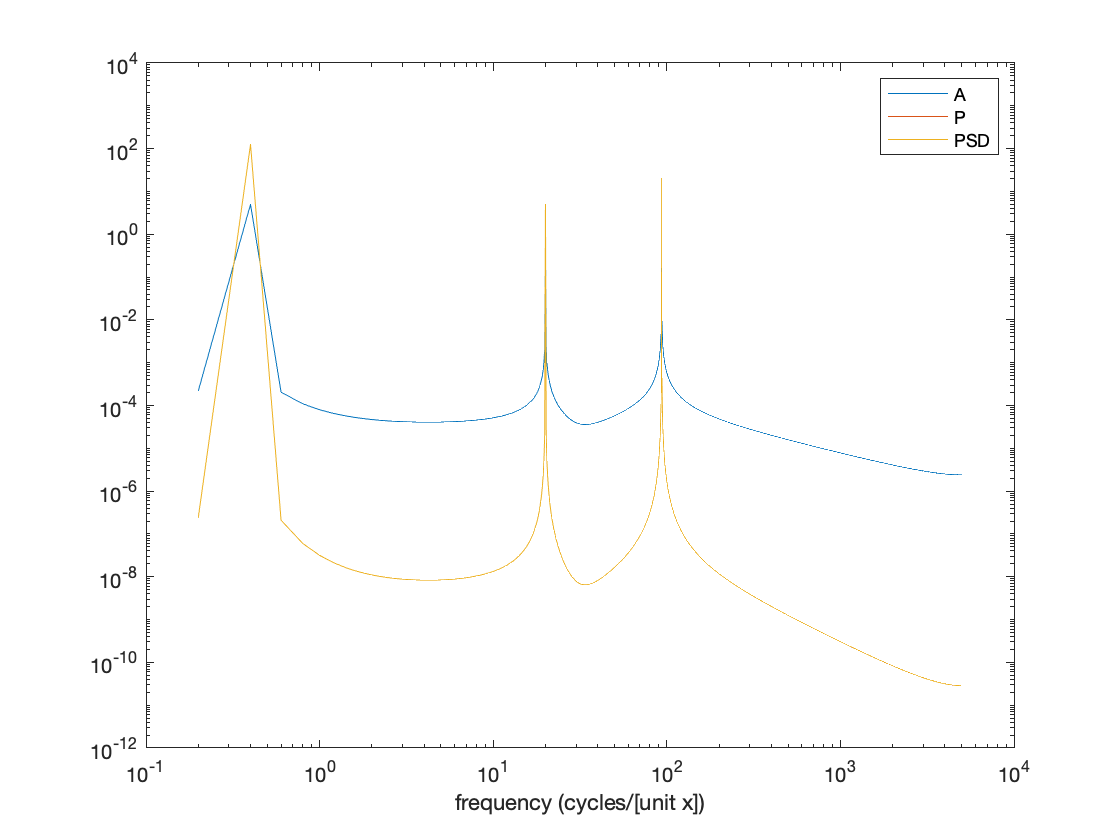



%Plot all on one figure
figure(5);clf
loglog(fp,Ap,fp,Pp./0.2,fPSD,PSD)
legend('A','P','PSD')
xlabel('frequency (cycles/[unit x])')

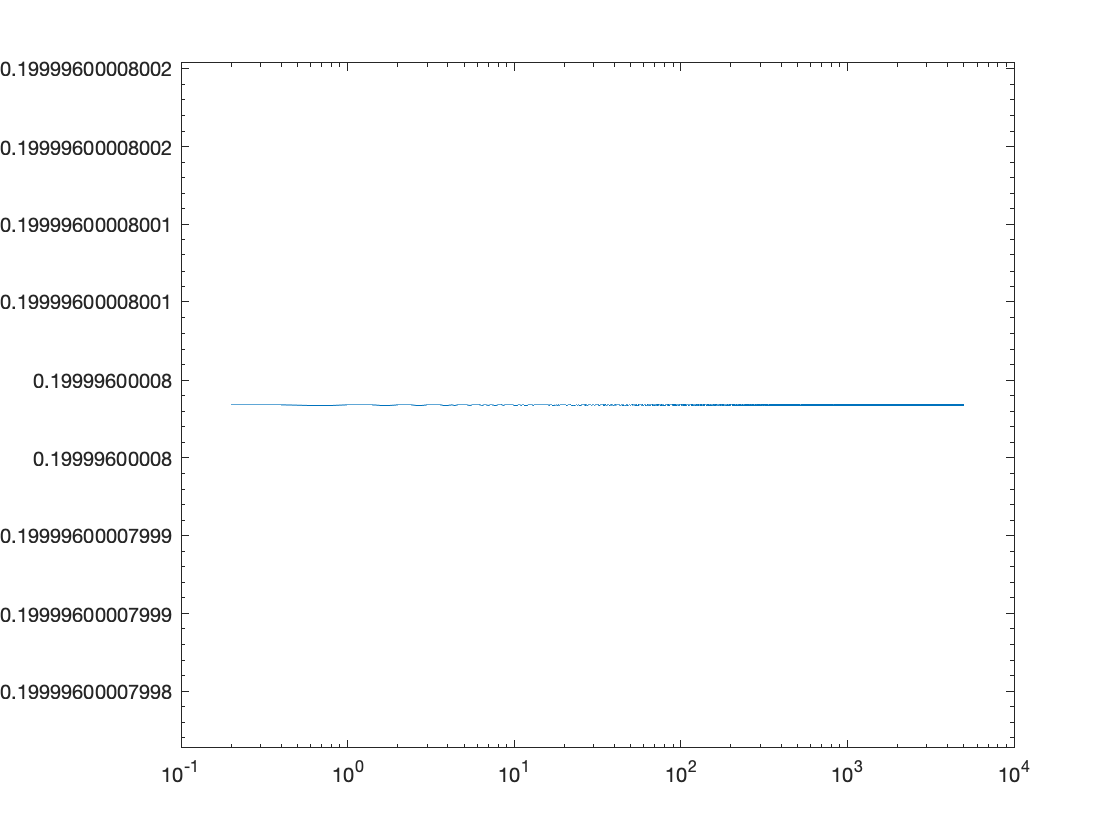


figure(6);clf
loglog(fp,Pp./PSD)

Note the dashed lines showing the frequencies of the original sine wave components. You should see that the original 